% load cell IDs for cells recorded across multiple days
cellUIDs.animal4612{1} = "4612_ 5";
cellUIDs.animal4612{2} = ["4612_ 4", "4612_ 6"];
cellUIDs.animal4627{1} = ["4627_ 2", "4627_ 1", "4627_ 3"];
cellUIDs.animal4627{2} = ["4627_ 2", "4627_ 1", "4627_ 3"];
cellUIDs.animal3300{1} = ["3300_ 1", "3300_ 2", "3300_ 3", "3300_ 4"];
cellUIDs.animal3300{2} = ["3300_ 5"];
cellUIDs.animal3300{3} = ["3300_ 6", "3300_ 7", "3300_ 8", "3300_ 9", "3300_10", "3300_11", "3300_12"];
cellUIDs.animal3300{4} = ["3300_13", "3300_ 2", "3300_14", "3300_ 1", "3300_15", "3300_16", "3300_17", "3300_18", "3300_ 3"];
cellUIDs.animal5646{1} = ["5646_ 1", "5646_ 2", "5646_ 3", "5646_ 4"];

cellUIDs.animal4094{1} = ["4094_ 1"];
cellUIDs.animal5628{1} = ["5628_ 1"];
cellUIDs.animal5628{2} = ["5628_ 2", "5628_ 3", "5628_ 4"];
cellUIDs.animal5628{3} = ["5628_ 5", "5628_ 6"];
cellUIDs.animal5628{4} = ["5628_ 7"];

cellUIDs.animal7776{1} = ["7776_ 1", "7776_ 2", "7776_ 3"];
cellUIDs.animal7776{2} = ["7776_ 4"];
cellUIDs.animal7776{3} = ["7776_ 5", "7776_ 6", "7776_ 7"];
cellUIDs.animal7776{4} = ["7776_ 8"];

cellUIDs.animal7777{1} = ["7777_ 1"];
cellUIDs.animal7777{2} = ["7777_ 2"];

cellUIDs.animal7992{1} = ["7992_ 1", "7992_ 2", "7992_ 3", "7992_ 4"];
cellUIDs.animal7992{2} = ["7992_ 5"];
cellUIDs.animal7992{3} = ["7992_ 6", "7992_ 7", "7992_ 8"];
cellUIDs.animal7992{4} = ["7992_ 9"];

cellUIDs.animal7995{1} = ["7995_ 1"];
cellUIDs.animal7995{2} = ["7995_ 2"];

% Options for data alignment
ops.cameraTriggerChan = 11;
ops.treadmillChan = 14;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 4612

Animal 4612 Day 5 sleep

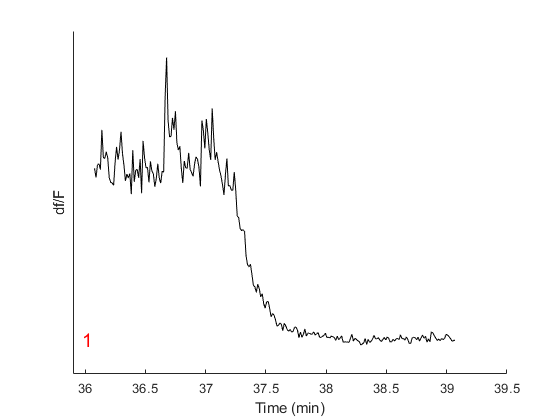

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\JR_22_03_09_confon_GCaMP_4612_220309_171624';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal4612_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);


Animal 4612 Day 6 sleep

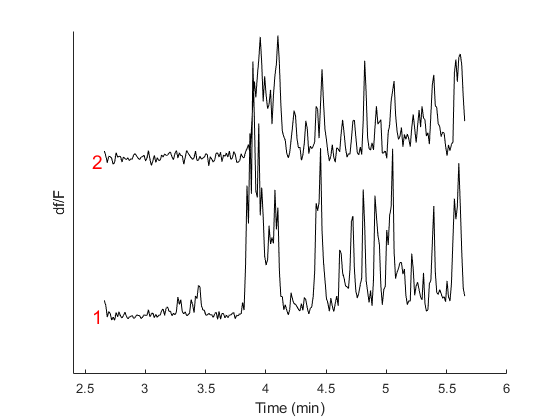

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\JR_22_05_11_confon_GCaMP_4612_220511_180252';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal4612_sleep(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 4627

Animal 4627 Day 5 sleep

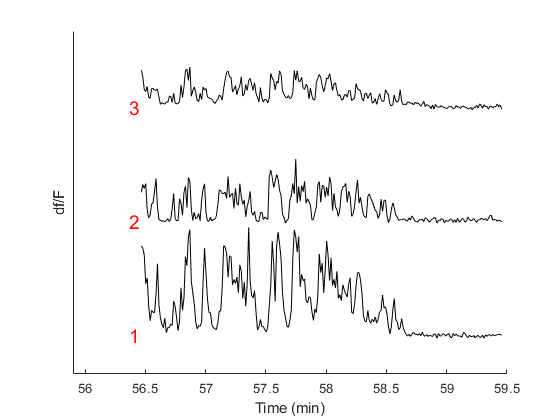

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\JR_22_05_09_confon_GCaMP_4627_220509_154655';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal4627_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 4627 Day 6 sleep

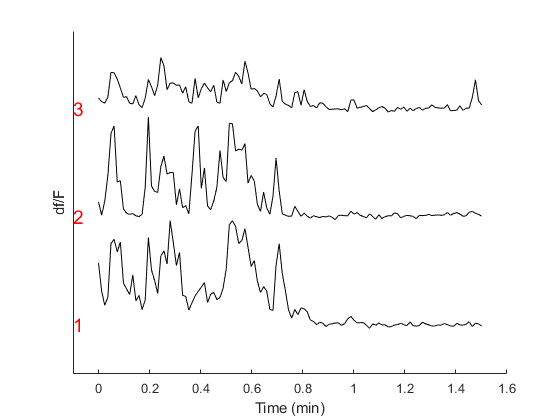

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\JR_22_07_12_confon_GCaMP_4627_220712_145339';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal4627_sleep(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 3300 (aka animal 1)

Animal 3300 Day 1 sleep

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\JR_22_08_03_confon_GCaMP_animal_1_220803_144226';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

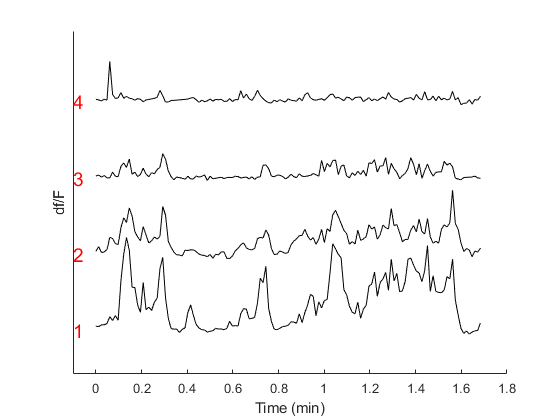

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal3300_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 3300 Day 2 sleep

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\JR_22_08_05_confon_GCaMP_animal_1_220805_151711';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

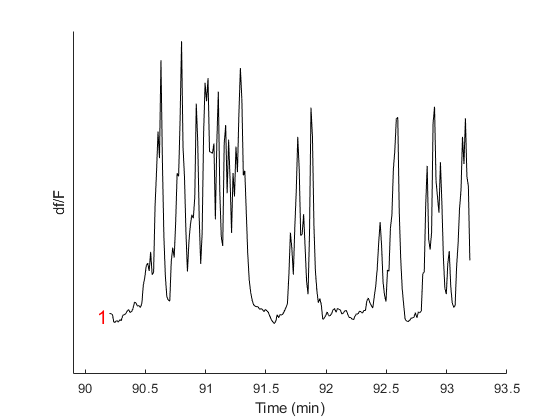

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal3300_sleep(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 3300 Day 3 sleep

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\JR_22_08_09_confon_GCaMP_animal_1_220809_140641';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

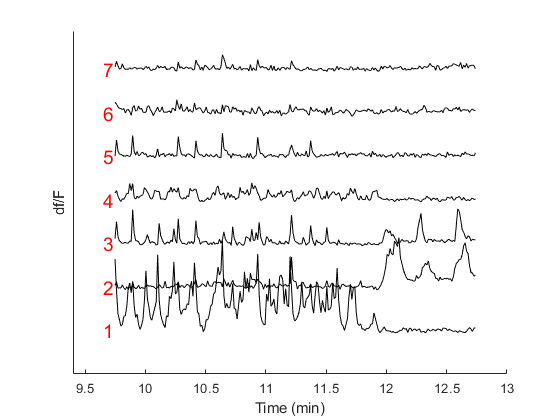

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal3300_sleep(3).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 3300 Day 4 sleep

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\JR_22_08_12_confon_GCaMP_animal_1_220812_160050';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

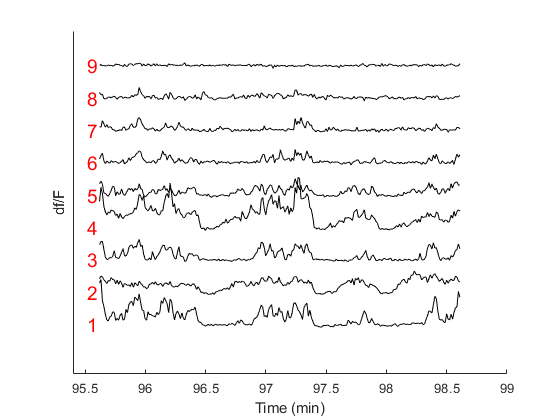

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal3300_sleep(4).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 5646 (aka animal 2)

Animal 5646 Day 1 sleep

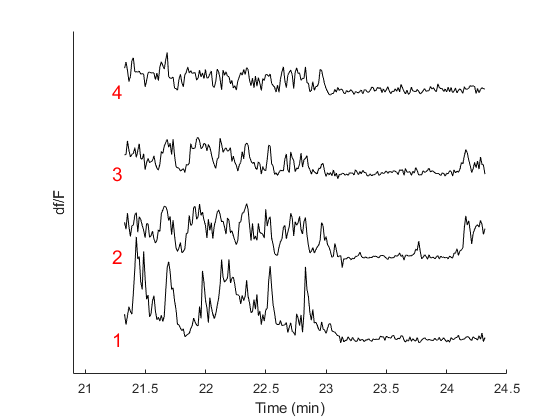

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\JR_22_10_13_confon_GCaMP_animal_5646_221013_152101';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal5646_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);


## Animal 4094 -- from Geoffrey

Animal 4094 Day 1 sleep

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\Test_Vehicle_220920_154142';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\field1';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\ArousalScore.mat', 'Animal4094')

% Analyze session
Animal4094_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, Animal4094(1).output.ArousalScore);

## Animal 5628

Animal 5628 Day 1

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX_221123_152657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;
load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\ArousalScore.mat', 'Animal5628')

% Analyze session
Animal5628_sleep(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, Animal5628(1).output.ArousalScore);

Animal 5628 Day 2

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\AFDX1mM_221209_125812';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\preAFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

% Analyze session
Animal5628_sleep(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, Animal5628(2).output.ArousalScore);

Animal 5628 Day 3

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX1mM_221221_143557';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

% Analyze session
Animal5628_sleep(3).output = analyzeSleepBoutActivity(imgStruct, stateInts, Animal5628(3).output.ArousalScore);

Animal 5628 Day 4

basepath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX1mM_221222_150023';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Jacob Ratliff\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

% Analyze session
Animal5628_sleep(4).output = analyzeSleepBoutActivity(imgStruct, stateInts, Animal5628(4).output.ArousalScore);

% Options for data alignment
ops.cameraTriggerChan = 10;
ops.treadmillChan = 11;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 7776

Animal 7776 Day 1

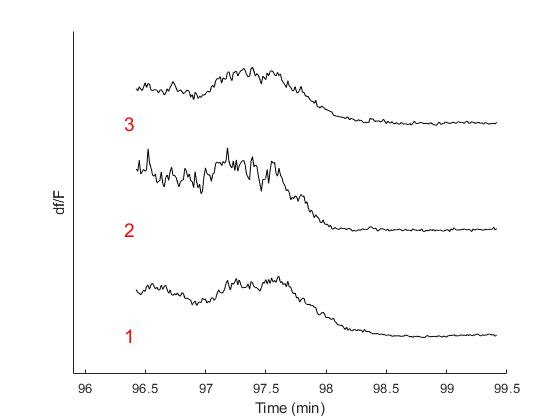

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720\Imaging_04_16_2024_85um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7776(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7776 Day 2

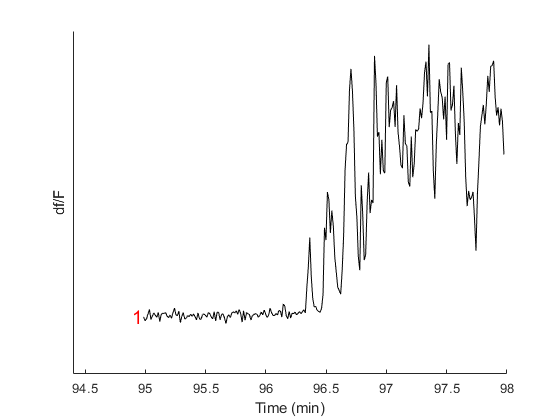

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748\Imaging_04_17_2024_200um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7776(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7776 Day 3

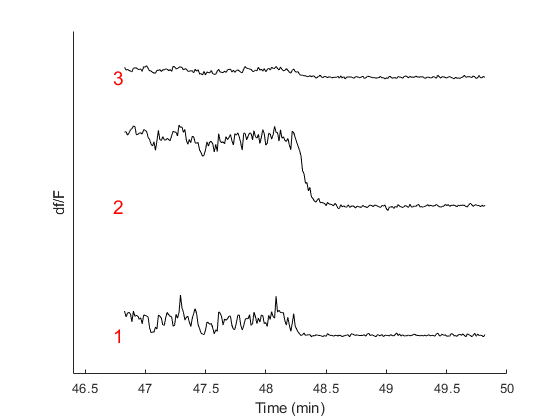

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444\Imaging_04_18_2024_15um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7776(3).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7776 Day 4

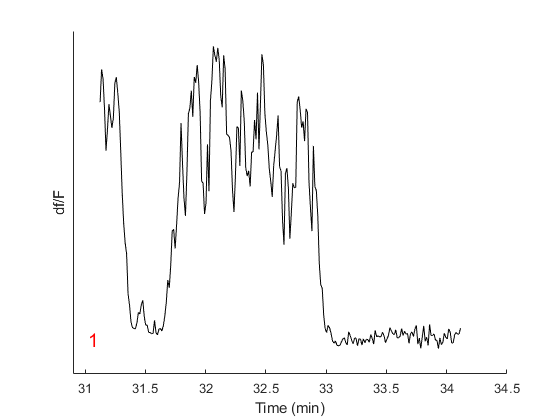

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705\Imaging_04_19_2024_70um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7776(4).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 7777

Animal 7777 Day 1

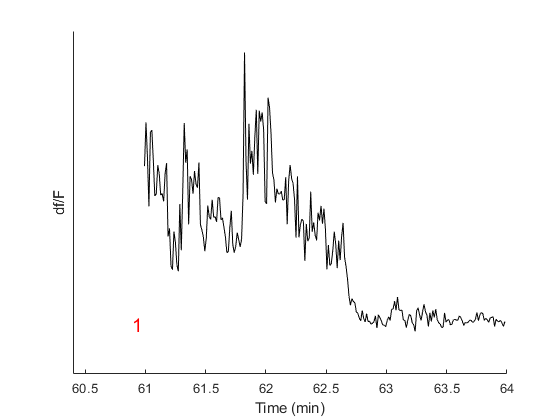

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828\05-01-2024-30um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7777(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7777 Day 2

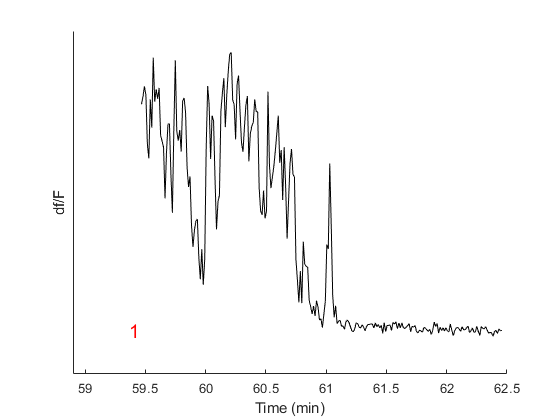

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803\Imaging_05-08-2024-80um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7777(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 7992

Animal 7992 Day 1

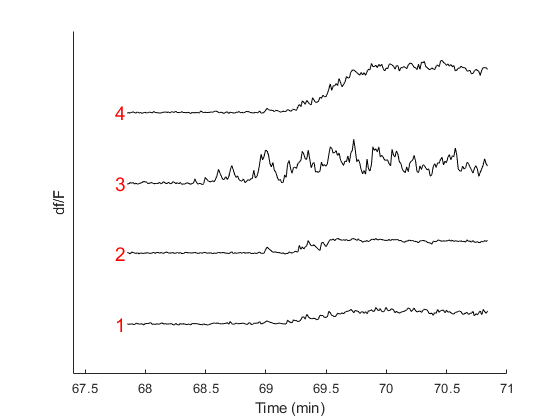

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003\Imaging_04_16_2024_70um_000';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7992(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7992 Day 2

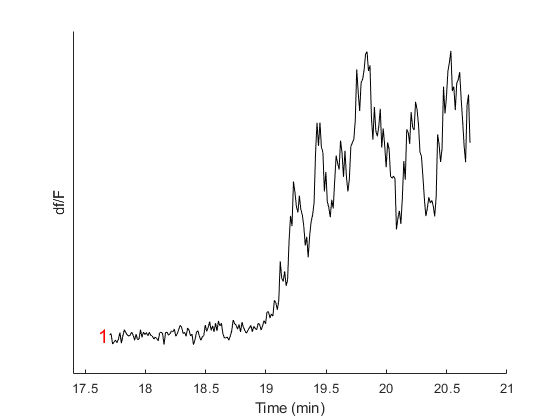

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030\Imaging_04_18_2024_10um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7992(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7992 Day 3

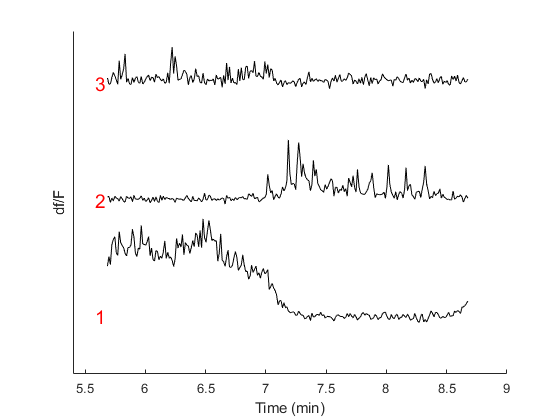

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238\Imaging_04_19_2024_155um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7992(3).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7992 Day 4

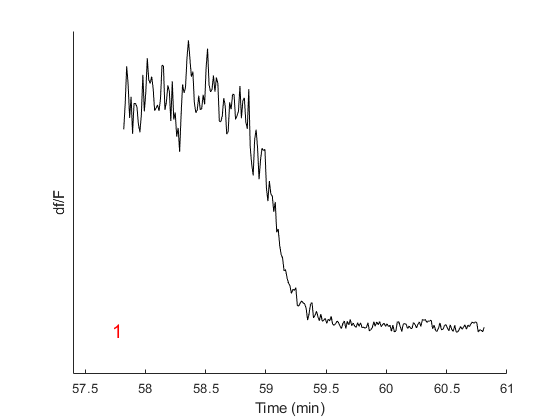

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051\Imaging_04_22_2024_140um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7992(4).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

## Animal 7995

Animal 7995 Day 1

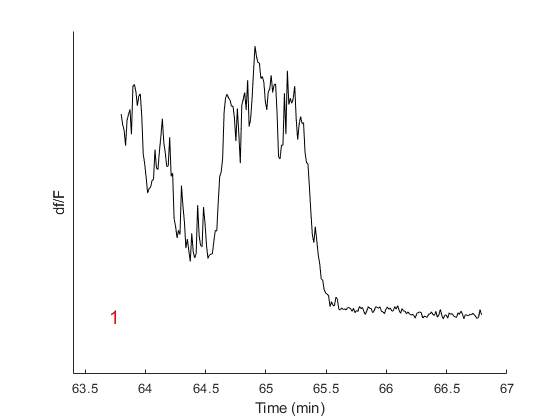

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221\Imaging_05-01-2024-0um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7995(1).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);

Animal 7995 Day 2

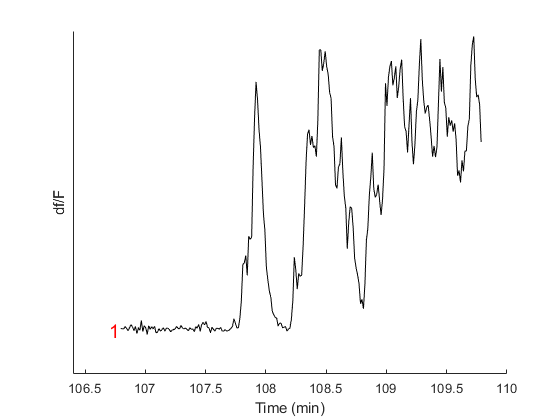

basepath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'W:\Batista Lab\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726\Imaging_05-14-2024-170um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load sleep bouts and align to imaging
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate - imgStruct.firstScopeFrameTime;
stateInts.REM = SleepState.ints.REMstate - imgStruct.firstScopeFrameTime;

arousalScore = extractArousalScore(basepath, 'deltaChan', SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

Loading arousal score calculations from previous run...



% Analyze session
Animal7995(2).output = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore);



combined = combineAcrossAnimals([Animal4612_sleep Animal4627_sleep Animal3300_sleep Animal5646_sleep ...
    Animal4094_sleep Animal5628_sleep Animal7776 Animal7777 Animal7992 Animal7995]);
cellUIDs.list = [cellUIDs.animal4612{:} cellUIDs.animal4627{:} cellUIDs.animal3300{:} cellUIDs.animal5646{:}...
    cellUIDs.animal4094{:} cellUIDs.animal5628{:} cellUIDs.animal7776{:} cellUIDs.animal7777{:}...
    cellUIDs.animal7992{:} cellUIDs.animal7995{:}];

celltypes = SSTnNOS.getCellType(cellUIDs.list);

Loading cell type data extracted 28-May-2024 14:55:39


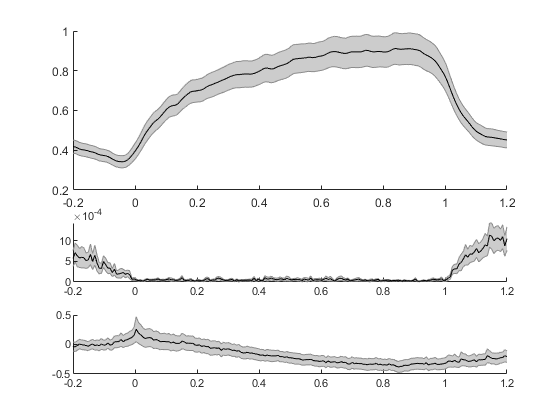

[~, uniInds] = unique(cellUIDs.list);
cellInds = intersect(find(celltypes == 1), uniInds);

figure
subplot(4,1,1:2)
shadedErrorBar(combined.NREM.time, mean(smoothdata(combined.NREM.deltaF(:,cellInds),1,'gaussian',5),2,'omitnan'), std(combined.NREM.deltaF(:,cellInds),0,2,'omitnan')./sqrt(size(combined.NREM.deltaF,2)))

subplot(4,1,3)
shadedErrorBar(combined.NREM.time, mean(combined.NREM.tread,2,'omitnan'), std(combined.NREM.tread,0,2,'omitnan')./sqrt(size(combined.NREM.tread,2)))

subplot(4,1,4)
shadedErrorBar(combined.NREM.time, mean(combined.NREM.arousal,2,'omitnan'), std(combined.NREM.arousal,0,2,'omitnan')./sqrt(size(combined.NREM.arousal,2)))

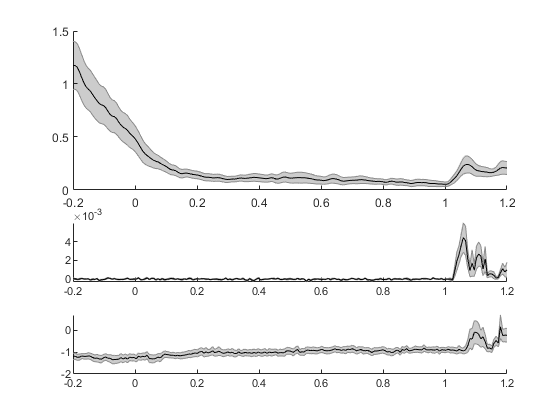

figure
subplot(4,1,1:2)
shadedErrorBar(combined.REM.time, mean(smoothdata(combined.REM.deltaF,1,'gaussian',5),2,'omitnan'), std(smoothdata(combined.REM.deltaF,1,'gaussian',5),0,2,'omitnan')./sqrt(sum(any(isnan(combined.REM.deltaF),1))))

subplot(4,1,3)
shadedErrorBar(combined.REM.time, mean(combined.REM.tread,2,'omitnan'), std(combined.REM.tread,0,2,'omitnan')./sqrt(sum(any(isnan(combined.REM.deltaF),1))))

subplot(4,1,4)
shadedErrorBar(combined.REM.time, mean(combined.REM.arousal,2,'omitnan'), std(combined.REM.arousal,0,2,'omitnan')./sqrt(sum(any(isnan(combined.REM.deltaF),1))))

function combinedOutput = combineAcrossAnimals(animals)

NREM.deltaF = [];
NREM.tread = [];
NREM.arousal = [];
REM.deltaF = [];
REM.tread = [];
REM.arousal = [];
for i = 1:length(animals)
    NREM.deltaF = [NREM.deltaF, animals(i).output.NREM.deltaF];
    NREM.tread = [NREM.tread, animals(i).output.NREM.treadmill];
    NREM.arousal = [NREM.arousal, animals(i).output.NREM.arousal];
    
    REM.deltaF = [REM.deltaF, animals(i).output.REM.deltaF];
    REM.tread = [REM.tread, animals(i).output.REM.treadmill];
    REM.arousal = [REM.arousal, animals(i).output.REM.arousal];

end

combinedOutput.NREM.deltaF = NREM.deltaF;
combinedOutput.NREM.tread = NREM.tread;
combinedOutput.NREM.arousal = NREM.arousal;
combinedOutput.NREM.time = animals(i).output.NREM.boutTime;
combinedOutput.REM.deltaF = REM.deltaF;
combinedOutput.REM.tread = REM.tread;
combinedOutput.REM.arousal = REM.arousal;
combinedOutput.REM.time = animals(i).output.REM.periEventTime;

end

function relativeActivity = analyzeSleepBoutActivity(imgStruct, stateInts, arousalScore)

minimumBoutLength = 5;
stateInts.NREM(diff(stateInts.NREM,1,2) < minimumBoutLength, :) = [];

% Get NREM bout activity activity
% relativeActivity.NREMBout = boutRelativeActivity(imgStruct, stateInts.NREM, arousalScore);
[boutAvg.deltaF, boutTime] = interpolateAverageBout(imgStruct.deltaF.data, imgStruct.deltaF.time, ...
    stateInts.NREM, [-.2 1.2]);
[boutAvg.arousal, boutTime] = interpolateAverageBout(arousalScore.score', arousalScore.timestamps, ...
    stateInts.NREM, [-.2 1.2]);
[boutAvg.treadmill, boutTime] = interpolateAverageBout(imgStruct.AlignedData.treadmillData.data',...
    imgStruct.AlignedData.treadmillData.time, stateInts.NREM, [-.2 1.2]);

%%% Get peri-REM activity %%%
% bounds = [-10 15];
% 
% if ~isempty(stateInts.REM)
%     upsampleFactor = 1000;
%     upsampledTime = interp1(1:length(imgStruct.deltaF.time), imgStruct.deltaF.time, 1:(1/upsampleFactor):length(imgStruct.deltaF.time), 'linear', 'extrap');
%     upsampledDeltaF = interp1(imgStruct.deltaF.time(1:end), imgStruct.deltaF.data', upsampledTime, 'linear', 'extrap')';
%     
%     [periEventAvg.deltaF, periTime] = interpolatePeriEventAverage(upsampledDeltaF, ...
%         upsampledTime', stateInts.REM(:,1), bounds);
%     [periEventAvg.arousal, periTime] = interpolatePeriEventAverage(arousalScore.score', ...
%         arousalScore.timestamps, stateInts.REM(:,1), bounds);
%     [periEventAvg.treadmill, periTime] = interpolatePeriEventAverage(imgStruct.AlignedData.treadmillData.data', ...
%         imgStruct.AlignedData.treadmillData.time, stateInts.REM(:,1), bounds);
% else
%     periTime = bounds(1):(range(bounds)/(200 - 1)):bounds(2); % beware the kludge
%     periEventAvg.deltaF = nan(200,1);
%     periEventAvg.arousal = nan(200,1);
%     periEventAvg.treadmill = nan(200,1);
%     periEventAvg.periTime = periTime;
% end

[REMboutAvg.deltaF, REMboutTime] = interpolateAverageBout(imgStruct.deltaF.data, imgStruct.deltaF.time, ...
    stateInts.REM, [-.2 1.2]);
[REMboutAvg.arousal, REMboutTime] = interpolateAverageBout(arousalScore.score', arousalScore.timestamps, ...
    stateInts.REM, [-.2 1.2]);
[REMboutAvg.treadmill, REMboutTime] = interpolateAverageBout(imgStruct.AlignedData.treadmillData.data',...
    imgStruct.AlignedData.treadmillData.time, stateInts.REM, [-.2 1.2]);


% Set output
relativeActivity.NREM.deltaF = boutAvg.deltaF;
if size(boutAvg.deltaF,1) == 1
    relativeActivity.NREM.deltaF = boutAvg.deltaF';
end

relativeActivity.NREM.boutTime = boutTime;
relativeActivity.NREM.arousal = boutAvg.arousal;
relativeActivity.NREM.treadmill = boutAvg.treadmill;
% relativeActivity.REM.deltaF = periEventAvg.deltaF;
% relativeActivity.REM.periEventTime = periTime;
% relativeActivity.REM.arousal = periEventAvg.arousal;
% relativeActivity.REM.treadmill = periEventAvg.treadmill;
relativeActivity.REM.deltaF = REMboutAvg.deltaF;
relativeActivity.REM.periEventTime = REMboutTime;
relativeActivity.REM.arousal = REMboutAvg.arousal;
relativeActivity.REM.treadmill = REMboutAvg.treadmill;

end

function relativeActivity = boutRelativeActivity(imgStruct, boutIntervalsSec, arousalScore)

% Upsample deltaF signals
upFactor = 1000;
upsampledTime = interp1(1:length(imgStruct.deltaF.time), imgStruct.deltaF.time, 1:(1/upFactor):length(imgStruct.deltaF.time), 'linear', 'extrap');
upsampledDeltaF = interp1(imgStruct.deltaF.time(1:end), imgStruct.deltaF.data', upsampledTime, 'linear', 'extrap')';
nCells = size(imgStruct.deltaF.data,1);


%%%% Extract intra bout activity %%%%
startingPrct = -.2;
endingPrct = 1.2;
numSamples = 200;

intraBoutSnips = zeros(length(boutIntervalsSec) - 1, numSamples, nCells);
intraBoutTread = zeros(length(boutIntervalsSec) - 1, numSamples);
intraBoutArousal = zeros(length(boutIntervalsSec) - 1, numSamples);

for i = 1:(length(boutIntervalsSec) - 1)
    % grab intra-Bout data
    intraBoutInt = boutIntervalsSec(i,:);
    % strech/shrink data to fit normalized time
    startTime = intraBoutInt(1) + range(intraBoutInt)*startingPrct;
    endTime = intraBoutInt(2) + range(intraBoutInt)*(endingPrct - 1);
    normalizedTime = startTime:((endTime-startTime)/(numSamples-1)):endTime;
    intraBoutSnips(i,:,:) = interp1(upsampledTime,upsampledDeltaF',normalizedTime);
    intraBoutTread(i,:) = interp1(imgStruct.AlignedData.treadmillData.time,...
        imgStruct.AlignedData.treadmillData.data, normalizedTime);
    intraBoutArousal(i,:) = interp1(arousalScore.timestamps,...
        arousalScore.score, normalizedTime);
end

% Plot intra-movement activity
figure; subplot(5,1,1:3); hold on
timePrct = startingPrct:((endingPrct-startingPrct)/(numSamples-1)):endingPrct;
plot(timePrct, squeeze(mean(intraBoutSnips,1,'omitnan')),'color',[.7 .7 .7])
plot(timePrct, squeeze(mean(mean(intraBoutSnips,1,'omitnan'),3,'omitnan')),'k','LineWidth',2)
xlim([startingPrct endingPrct])
plot([0 0], ylim,'k--')
plot([1 1], ylim, 'k--')
plot(xlim, [0 0], 'k--')
ylabel('Average df/F')
title('SST/nNOS cell activity between movement bouts')

subplot(5,1,4)
shadedErrorBar(timePrct,mean(smoothdata(intraBoutTread,2,'gaussian',[10 0]),1,'omitnan'),...
    std(smoothdata(intraBoutTread,2,'gaussian',[10 0]),0,1,'omitnan'))
xlim([startingPrct endingPrct])
ylabel('Locomotion')
yticks([])

subplot(5,1,5)
shadedErrorBar(timePrct,mean(intraBoutArousal,1,'omitnan'),...
    std(intraBoutArousal,0,1,'omitnan'))
xlim([startingPrct endingPrct])
xlabel('Normalized intramovement time (%)')
ylabel('Arousal Score')

%%%% Output %%%%
relativeActivity.intraBoutActivity.deltaF.data = intraBoutSnips;
relativeActivity.intraBoutActivity.deltaF.time = timePrct;
relativeActivity.intraBoutActivity.tread.data = smoothdata(intraBoutTread,2,'gaussian',[10 0]);
relativeActivity.intraBoutActivity.tread.time = timePrct;
relativeActivity.intraBoutActivity.arousal.data = intraBoutArousal;
relativeActivity.intraBoutActivity.arousal.time = timePrct;
%%%%%%%%%%%%%%%%

end